## 版本内容

v5.4

简化网络，继承于v5.3

## 仿真系统及DRL系统基本参数信息

### 仿真系统初始化

clc;clear;close all
warning('off')
addpath(genpath(pwd))
cfg = Simulink.fileGenControl('getConfig');
work_dir = pwd;
cfg.CacheFolder = fullfile(work_dir,'Simulation cache folder');
cfg.CodeGenFolder  = fullfile(work_dir,'Simulation cache folder');
Simulink.fileGenControl('setConfig', 'config', cfg);

### 工况

cyc_name = 'WLTC'; % CLTCP WLTC
switch cyc_name
    case 'CLTCP'
        load('CLTCP.mat');
        cyc_time =Cycle(:,1);
        cyc_vel =Cycle(:,2);
        clear Cycle
    case 'WLTC'
        load('WLTC.mat');
        cyc_time =WLTC(:,1);
        cyc_vel =WLTC(:,2);
        clear WLTC
end

### DRL采样时间

ts = 1;

### 发动机OOL参数

load("Eng_param")

### DRL观测空间物理范围

obs_max = 1e4*[0.0020, 0.0090, 0.0100, 0.0100, 8.4000, 0.0100,...
               0.0056, 0.1011, 2.8000,      0, 0.0001, 0.0132,...
               0.0740, 2.6065, 0.0339, 0.0949, 0.0117, 2.4444];
obs_min = 1e4*[0.0010, 0.0070,      0,      0, 0.8400,      0,...
                    0, -0.0005,     0, -2.8000,     0, -0.0032...
              -0.0694, -2.7092, -0.0030,    0, -0.0001, -2.7647];

### 奖励函数参数

rho_gas = 0.739;           % 95汽油密度 kg/L
Price_gas = 7.14;          % 92汽油油价 RMB/L
Price_elec = 1;            % 充电电价 RMB/kWh
k_gas = 1;                 % 油耗惩罚权重
k_elec = 1;                % 电耗惩罚权重
k_SOCpen = 3e-2;            % SOC惩罚权重
k_actsmo = 1e-2;           % action平滑性惩罚权重
rew_Zoom = 1;              % 奖励函数缩放系数
en_gas = 1;                % 油耗奖励参数使能
en_elec = 1;               % 电耗奖励参数使能
en_SOCpen = 1;             % SOC惩罚参数使能
en_actsmo = 1;             % 动作平滑惩罚参数使能
RBEMSEprew_ge = -9.88;     % WLTC 工况 Rule-Based EMS episode reward,油耗,电耗
RBEMSEprew_geS = -10.86;   % WLTC 工况 Rule-Based EMS episode reward,油耗,电耗,SOC惩罚
RBEMSEprew_geSa = -10.97;  % WLTC 工况 Rule-Based EMS episode reward,油耗,电耗,SOC惩罚，动作平滑

### 模型路径及DRL系统

mdl = "DRLHevIps";
VCU_Mode_Change(3)
VCU_Mode_2 = "DRLHevIps/xCU/xCU/VCU/Rule_Based_DataGen/DRL_EMS";
VCU_Mode_3 = "DRLHevIps/xCU/xCU/VCU/DRL_Based2_0/DRL_EMS";
agentblk = VCU_Mode_3;

### 模型运行时间

stop_time = cyc_time(end);

## 随机种子

previousRngState = rng(0,"twister");

## 创建env对象

obsInfo = rlNumericSpec([18 1], ...
                        LowerLimit=zeros(18,1), ...
                        UpperLimit=ones(18,1));
obsInfo.Name = "observation";
obsInfo.Description = "VCU Input";
actInfo = rlNumericSpec([1 1], ...
                        LowerLimit=-1,...
                        UpperLimit=1);
actInfo.Name = "action";
obsInfo.Description = "Eng Spd Mapping";
env = rlSimulinkEnv(mdl,agentblk,obsInfo,actInfo);
env.UseFastRestart = "on";

## 创建DRL-EMS智能体

### 官方文档

[https://ww2.mathworks.cn/help/releases/R2025b/reinforcement-learning/ref/rl.agent.rlsacagent.html#d126e79088](https://ww2.mathworks.cn/help/releases/R2025b/reinforcement-learning/ref/rl.agent.rlsacagent.html#d126e79088)

obs_dim = prod(obsInfo.Dimension);
act_dim = prod(actInfo.Dimension);

### Critic网络

% 观测路径 (处理 18维 State)
obsPath = [
    featureInputLayer(obs_dim, Name="obsInLyr")
    fullyConnectedLayer(128)
    layerNormalizationLayer
    reluLayer(Name="obsPathOutLyr")
    ];

% 动作路径 (处理 1维 Action)
actPath = [
    featureInputLayer(act_dim, Name="actInLyr")
    fullyConnectedLayer(128)
    layerNormalizationLayer
    reluLayer(Name="actPathOutLyr")
    ];

% 公共路径 (State + Action)
commonPath = [
    concatenationLayer(1, 2, Name="concat")
    fullyConnectedLayer(128, Name="fc1") 
    reluLayer
    fullyConnectedLayer(64, Name="fc2")  % 进一步收缩特征
    reluLayer
    fullyConnectedLayer(1, Name="QValue") % 输出 Q值
    ];

criticNet = dlnetwork;
criticNet = addLayers(criticNet, obsPath);
criticNet = addLayers(criticNet, actPath);
criticNet = addLayers(criticNet, commonPath);
criticNet = connectLayers(criticNet, "obsPathOutLyr", "concat/in1");
criticNet = connectLayers(criticNet, "actPathOutLyr", "concat/in2");

% 初始化两个 Critic (SAC 需要 Double Q-Learning)
critic1 = rlQValueFunction(initialize(criticNet), obsInfo, actInfo, ...
    ObservationInputNames="obsInLyr", ActionInputNames="actInLyr");
critic2 = rlQValueFunction(initialize(criticNet), obsInfo, actInfo, ...
    ObservationInputNames="obsInLyr", ActionInputNames="actInLyr");

### Actor网络

% 公共特征提取层 (Shared Layers)
actorCommonPath = [
    featureInputLayer(obs_dim, Name="obsIn")
    fullyConnectedLayer(128)
    layerNormalizationLayer
    reluLayer
    fullyConnectedLayer(128)
    layerNormalizationLayer
    reluLayer(Name="comOut")
    ];

% --- 均值分支 (Mean Branch) ---
% 输出范围 [-1, 1]，对应 Simulink 查表输入的范围
meanPath = [
    fullyConnectedLayer(64, Name="mFc")
    reluLayer
    fullyConnectedLayer(act_dim, Name="meanRaw")
    tanhLayer(Name="meanOutLyr") % Tanh 确保输出在 [-1, 1]
    ];

% --- 标准差分支 (Std Branch) ---
stdPath = [
    fullyConnectedLayer(64, Name="sFc")
    reluLayer
    fullyConnectedLayer(act_dim, Name="stdRaw")
    softplusLayer(Name="stdSoftplus") % 确保为正数
    ];

actorNet = dlnetwork;
actorNet = addLayers(actorNet, actorCommonPath);
actorNet = addLayers(actorNet, meanPath);
actorNet = addLayers(actorNet, stdPath);
actorNet = connectLayers(actorNet, "comOut", "mFc/in");
actorNet = connectLayers(actorNet, "comOut", "sFc/in");

% --- 动作概率分布定义 ---
% 使用 Gaussian Actor，MATLAB 会自动处理 log_prob
actor = rlContinuousGaussianActor(initialize(actorNet), obsInfo, actInfo, ...
    ActionMeanOutputNames="meanOutLyr", ...
    ActionStandardDeviationOutputNames="stdSoftplus", ... % 这里的输出必须>0
    ObservationInputNames="obsIn");

### 创建智能体

criticOptions = rlOptimizerOptions( ...
    Optimizer="adam", ...
    LearnRate=3e-4, ...
    GradientThreshold=1, ...
    L2RegularizationFactor=1e-4);

actorOptions = rlOptimizerOptions( ...
    Optimizer="adam", ...
    LearnRate=3e-4, ...
    GradientThreshold=1, ...
    L2RegularizationFactor=1e-4);

agentOptions = rlSACAgentOptions(...
    SampleTime = ts, ...
    DiscountFactor = 0.99, ... % 关注长期回报
    TargetSmoothFactor = 5e-3, ... 
    ExperienceBufferLength = 5e5, ... 
    MiniBatchSize = 256, ...
    CriticOptimizerOptions = criticOptions, ...
    ActorOptimizerOptions = actorOptions);

% 熵调节 (SAC 核心)
agentOptions.UseCriticTargetEntropy = true; 
% 如果发现 Agent 收敛太快导致过早停止探索，可手动调大 TargetEntropy
% agentOptions.EntropyWeightOptionsTargetEntropy = -act_dim; % 默认值通常是 -dim

DRLEMSagent = rlSACAgent(actor, [critic1 critic2], agentOptions);

## 训练DRLEMSagent

### 学习

% keepCount = 10; 
% targetDir = "Result/agentlog";
% cleanTimer = timer('ExecutionMode', 'fixedRate', ...
%     'Period', 300, ...
%     'TimerFcn', @(~,~) cleanOldAgents(targetDir, keepCount));
% start(cleanTimer);

maxepisodes = 500;
maxsteps = ceil(stop_time/ts);
trainingOpts = rlTrainingOptions( ...
    MaxEpisodes                = maxepisodes, ...
    MaxStepsPerEpisode         = maxsteps, ...
    SimulationStorageType      = "none", ...
    Plots                      = "training-progress", ...
    StopTrainingCriteria       = "none", ...
    SaveAgentCriteria          = "EpisodeReward", ...
    SaveAgentValue             = RBEMSEprew_geSa, ...
    SaveAgentDirectory         = "Result/agentlog", ...
    Verbose                    = true, ...
    UseParallel                = false);
rng(previousRngState);
trainResult = train(DRLEMSagent, env, trainingOpts);

### 正在模型 'DRLHevIps' 中搜索引用模型。
### 总共要构建 6 个模型。
### 启动串行模型编译。
### Bat 的模型引用仿真目标是最新的。
### ECU 的模型引用仿真目标是最新的。
### Eng 的模型引用仿真目标是最新的。
### Gen 的模型引用仿真目标是最新的。
### Mot 的模型引用仿真目标是最新的。
### VehPhy 的模型引用仿真目标是最新的。

编译摘要

编译了 0 个模型，共 6 个模型(6 个模型已经是最新的)
编译持续时间: 0h 0m 15.202s
Episode:   1/500 | Episode reward:   -79.18 | Episode steps: 1800 | Average reward:   -79.18 | Step Count: 1800 | Episode Q0:     0.02
Episode:   2/500 | Episode reward:   -53.54 | Episode steps: 1800 | Average reward:   -66.36 | Step Count: 3600 | Episode Q0:    -0.41
Episode:   3/500 | Episode reward:   -68.91 | Episode steps: 1800 | Average reward:   -67.21 | Step Count: 5400 | Episode Q0:    -0.32
Episode:   4/500 | Episode reward:   -68.16 | Episode steps: 1800 | Average reward:   -67.45 | Step Count: 7200 | Episode Q0:    -0.01
Episode:   5/500 | Episode reward:   -59.94 | Episode steps: 1800 | Average reward:   -65.95 | Step Count: 9000 | Episode Q0:    -0.34
Episode:   6/500 | Episode reward:   -63.34 | Episode steps: 18

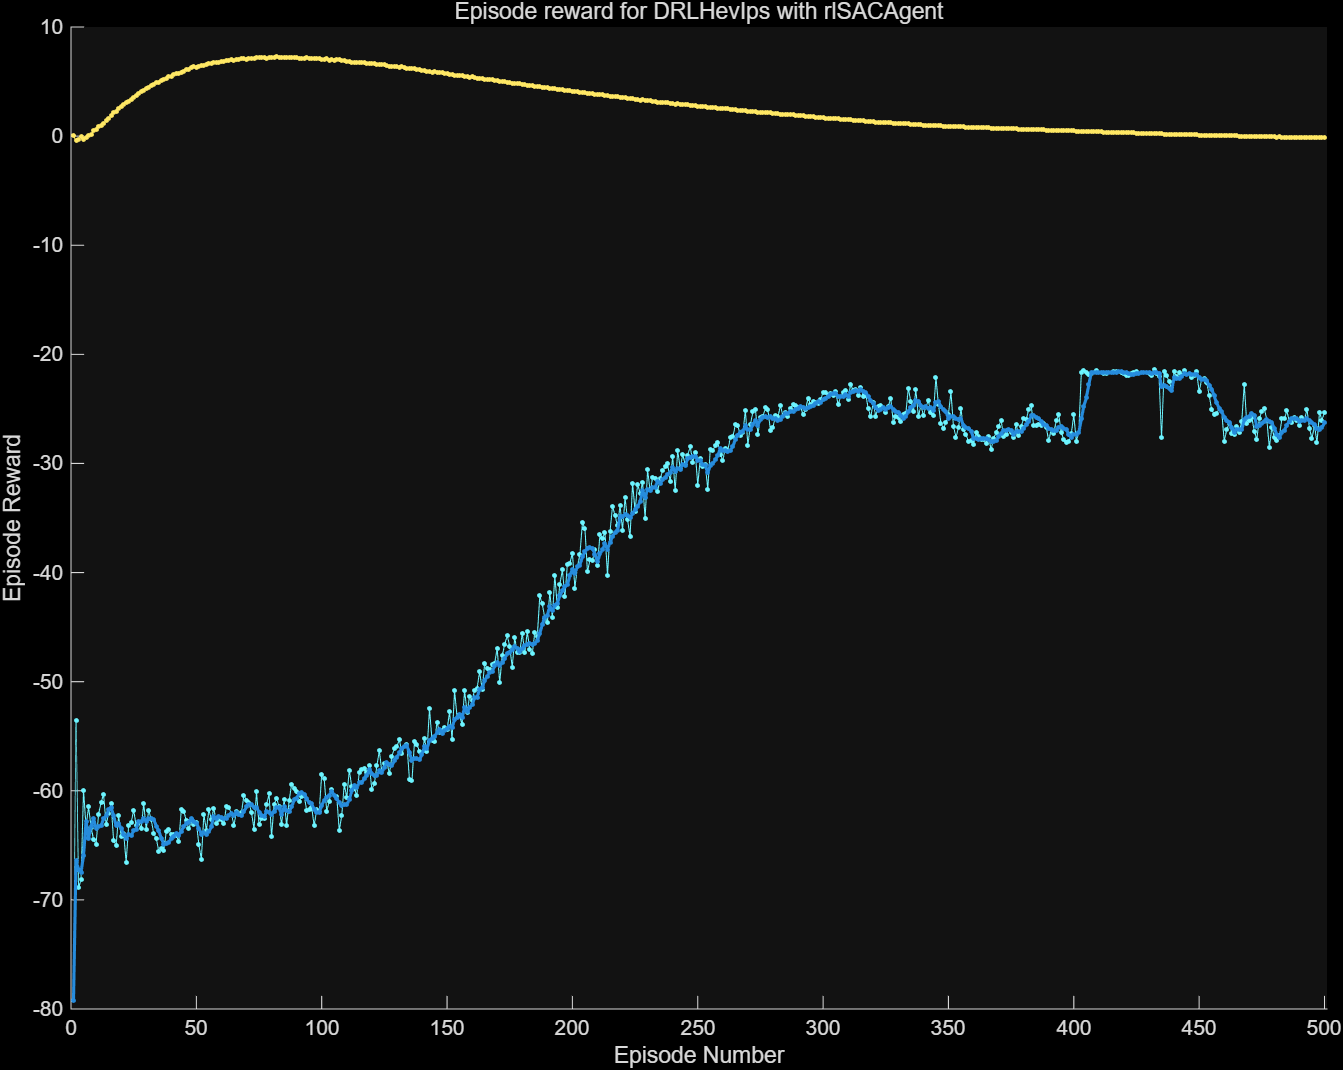

save('Result/DRLEMSagent.mat', 'DRLEMSagent');
save('Result/trainResult.mat', 'trainResult');

% stop(cleanTimer);
% delete(cleanTimer);

### 再训练：加载已有智能体继续优化

if isfile("Result/DRLEMSagent.mat")
    load("Result/DRLEMSagent.mat","DRLEMSagent");
end

retrainEpisodes = 500;
trainingOpts_retrain = rlTrainingOptions( ...
    MaxEpisodes                = retrainEpisodes, ...
    MaxStepsPerEpisode         = maxsteps, ...
    SimulationStorageType      = "none", ...
    Plots                      = "training-progress", ...
    StopTrainingCriteria       = "none", ...
    SaveAgentCriteria          = "EpisodeReward", ...
    SaveAgentValue             = RBEMSEprew_geSa, ...
    SaveAgentDirectory         = "Result/agentlog_retrain", ...
    Verbose                    = true, ...
    UseParallel                = false);

rng(previousRngState);
retrainResult = train(DRLEMSagent, env, trainingOpts_retrain);

save('Result/DRLEMSagent_retrain.mat', 'DRLEMSagent');
save('Result/retrainResult.mat', 'retrainResult');


function VCU_Mode_Change(param)
    HevIpsDictionaryObj = Simulink.data.dictionary.open('HevIps.sldd');
    HevIpsDataSectObj = getSection(HevIpsDictionaryObj, 'Design Data');
    signalObj = getEntry(HevIpsDataSectObj, 'VCU_Mode');
    signalValue = getValue(signalObj);
    signalValue.Value = param;
    setValue(signalObj, signalValue);
    saveChanges(HevIpsDictionaryObj);
end

function cleanOldAgents(folderPath, keepNum)
    files = dir(fullfile(folderPath, 'Agent*.mat'));
    if length(files) > keepNum
        [~, idx] = sort([files.datenum]);
        sortedFiles = files(idx);
        filesToDelete = sortedFiles(1 : end-keepNum);
        for k = 1:length(filesToDelete)
            filePath = fullfile(folderPath, filesToDelete(k).name);
            delete(filePath);
        end
    end
end